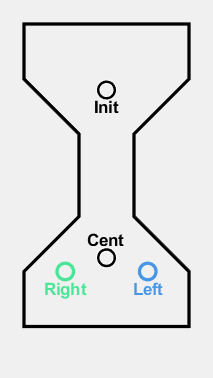

plotsize0 = [3.5 7];
f = figure(1); clf(1);
set(f, 'units', 'centimeters', 'position', [2 2, 4.5 8], 'Visible', 'on');
ha1 = axes;
set(ha1, 'units', 'centimeters', 'position', [.5 .5, plotsize0], ...
    'nextplot', 'add', 'ylim', [0 12], 'xlim', [0 6], ...
    'yscale', 'linear', 'ytick', [], 'fontsize', 8, 'FontName', 'Arial')

Color = GPSColor();
% 
% line([0 6], [1 1], 'color', 'k', 'linewidth', 2);
% line([0 0], [1 3], 'color', 'k', 'linewidth', 2);
% line([0 2], [3 5], 'color', 'k', 'linewidth', 2);
% line([2 2], [5 8], 'color', 'k', 'linewidth', 2);
% line([6 6], [1 3], 'color', 'k', 'linewidth', 2);
% line([6 4], [3 5], 'color', 'k', 'linewidth', 2);
% line([4 4], [5 8], 'color', 'k', 'linewidth', 2);
% 
% line([4 6], [8 10], 'color', 'k', 'linewidth', 2);
% line([2 0], [8 10], 'color', 'k', 'linewidth', 2);
% line([6 6], [10 12], 'color', 'k', 'linewidth', 2);
% line([0 0], [10 12], 'color', 'k', 'linewidth', 2);
% line([6 0], [12 12], 'color', 'k', 'linewidth', 2);

patch('XData', [0 6 6 4 4 6 6 0 0 2 2 0 0], 'YData', [1 1 3 5 8 10 12 12 10 8 5 3 1 1], ...
    'FaceColor', 'none', 'EdgeColor', 'k', 'LineWidth', 2);

viscircles([3, 9.6], 0.3, 'color', 'k', 'LineWidth', 1.5);
text(3, 9, 'Init', 'FontWeight','bold', 'HorizontalAlignment', 'center');
viscircles([3, 3.5], 0.3,  'color', 'k', 'LineWidth', 1.5);
text(3, 4.2, 'Cent', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

viscircles([4.5, 3], 0.3, 'color', Color.PortL, 'LineWidth', 2, 'EnhanceVisibility', false);
text(4.5, 2.4, 'Left', 'FontWeight','bold', 'HorizontalAlignment', 'center', 'Color', Color.PortL);
viscircles([1.5, 3], 0.3,  'color', Color.PortR, 'LineWidth', 2, 'EnhanceVisibility', false);
text(1.5, 2.4, 'Right', 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'Color', Color.PortR);

axis off

% printeps(1, 'MazeDiagram');
% print(f, '-dpng', 'MazeDiagram')
